Suponha que os motores de um podem falhar com probabilidade p e que as falhas são independentes entre motores. Suponha ainda que o avião se despenha se mais de metade dos motores falharem. Nestas condições, prefere voar num avião com 2 ou 4 motores? Utilize a distribuição que considerar mais adequada

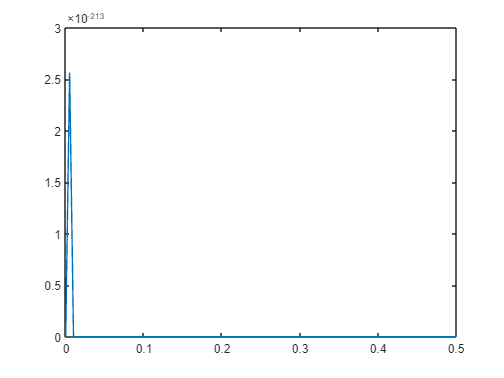

E = 1e5;

k = 2;

r = 0;
i = 1;

for p = 0:0.005:0.5
    r(i) = binomial_dist(E,k,p);
    i = i+1;
end

plot((0:0.005:0.5), r);

Função Binomial

function r = binomial_dist(e, k, p)
    comb = nchoosek(e, k);
    a = comb * p^k;
    r = a * (1-p)^(e-k);
end